# Visualizing the Bungee Jump

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code defines the equations and assumptions from the previous section.

syms y(t) b k
m = 75

m = 75

assume(y(t), "real")
assume([b k], "positive")
bungeeEqn = m*diff(y, t, 2) + b*diff(y, t) + k*y == 0

$$bungeeEqn(t) = 75\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+b\,\frac{\partial }{\partial t}y\left(t\right)+k\,y\left(t\right)=0$$

ic = y(0) == 75

$$ic = y\left(0\right)=75$$

dy(t) = diff(y, t)

$$dy(t) = \frac{\partial }{\partial t}y\left(t\right)$$

ic2 = dy(0) == 0

$$ic2 = \left({\left(\frac{\partial }{\partial t}y\left(t\right)\right)|}_{t=0}\right)=0$$

## Task 1

The initial position of the bungee jumper is stored in `ic` and the initial velocity is stored in `ic2`.

The `dsolve` function can solve a differential equation with multiple initial conditions.

`sol` `=` `dsolve``(``diffEqn``,` `[``cond1` `cond2` `cond3` `...``])`

ysol = dsolve(bungeeEqn, [ic ic2])

$$ysol = \begin{array}{l} \frac{75\,{\mathrm{e}}^{-t\,\left(\frac{b}{150}-\frac{\sigma_{1}}{150}\right)}\,\left(b+\sigma_{1}\right)}{2\,\sigma_{1}}-\frac{75\,{\mathrm{e}}^{-t\,\left(\frac{b}{150}+\frac{\sigma_{1}}{150}\right)}\,\left(b-\sigma_{1}\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{b^{2}-300\,k} \end{array}$$

## Task 2

The solution depends on the parameters *b* and *k*. In order to plot the solution, you will need to substitute values for these parameters.

yequil = subs(ysol, [b k], [4 8])

$$yequil = -\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{t\,\left(-\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\right)}\,\left(4+\sqrt{2384}\,\mathrm{i}\right)\,\mathrm{i}}{4768}-\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{-t\,\left(\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\right)}\,\left(-4+\sqrt{2384}\,\mathrm{i}\right)\,\mathrm{i}}{4768}$$

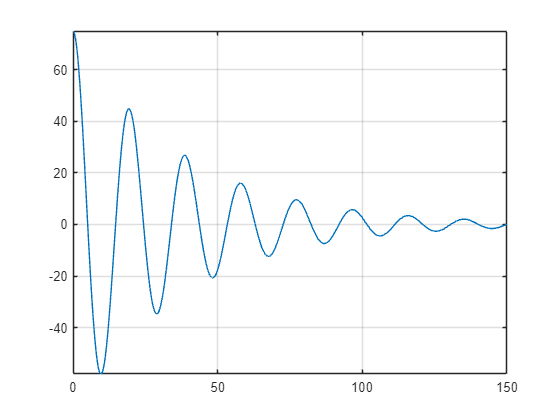

fplot(yequil, [0 150])
grid on

## Task 3

The plot shows the position of the bungee jumper relative to equilibrium. To instead plot the height of the bungee jumper relative to the ground, you can apply a shift to the function.

The bungee cord's equilibrium length is 75 meters, and the height of the bridge is 152 meters. So the bungee jumper is 77 meters off the ground at equilibrium.

ygnd = yequil + 77

$$ygnd = 77-\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{t\,\left(-\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\right)}\,\left(4+\sqrt{2384}\,\mathrm{i}\right)\,\mathrm{i}}{4768}-\frac{75\,\sqrt{2384}\,{\mathrm{e}}^{-t\,\left(\frac{2}{75}+\frac{\sqrt{2384}\,\mathrm{i}}{150}\right)}\,\left(-4+\sqrt{2384}\,\mathrm{i}\right)\,\mathrm{i}}{4768}$$

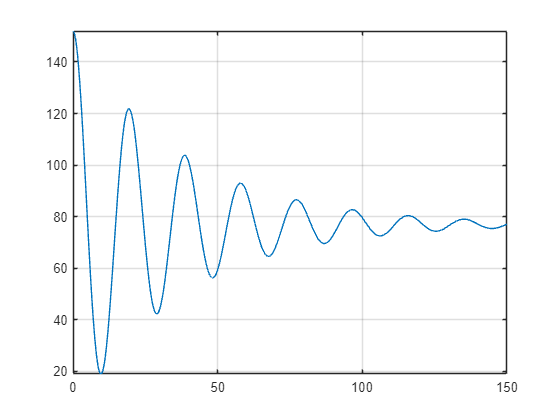

fplot(ygnd, [0 150])
grid on